%計算する対象
% x = tek0009;
% arrayLength = length(x);
vg = 0.2;
% スイープの時のみ2.5e3を選択
fs = 1e4;
% fs = 2.5e3;
list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,1);  
bodeData = zeros(numFiles,2);
for k = 1:numFiles
    Mx{k,1}= csvread(list(k).name,21,1,[21,1,10020,4]);
    for i = 1:10000
        Mx{k,2}(i,1) = i / fs;
        Mx{k,2}(i,2) = sqrt((Mx{k,1}(i,1)^2 + Mx{k,1}(i,2)^2 + Mx{k,1}(i,3)^2)/3) / vg;
        Mx{k,2}(i,3) = Mx{k,1}(i,4);
    end
%3列目にRMS値を入力
    bodeData(k,2) = ( rms(Mx{k,1}(:,1)) + rms(Mx{k,1}(:,2)) + rms(Mx{k,1}(:,3)) ) / vg;
    Mx{k,3} = bodeData(k,1);
%4列目に入力の周波数
    bodeData(k,1) = meanfreq(Mx{k,1}(:,4),fs);
    Mx{k,4} = bodeData(k,2);
%ピークの平均値を入力
    pks = findpeaks(Mx{k,2}(:,2),fs,'MinPeakDistance',1/(bodeData(k,2)+1));
    bodeData(k,3) = mean(pks);
    Mx{k,5} = bodeData(k,3);
%入力電圧のRMS値  
    bodeData(k,4) = peak2peak(Mx{k,1}(:,4));
    
end


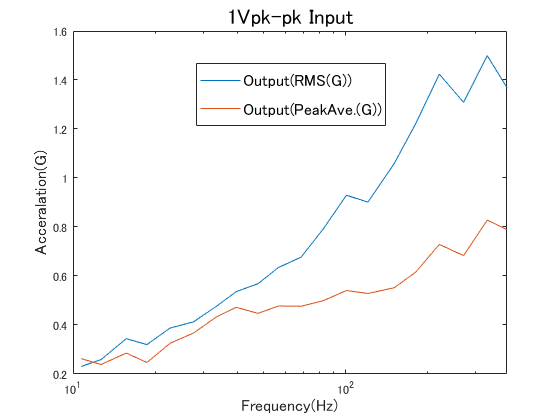


Voltage = num2str(round(bodeData(k,4)));
VoltageTitle = strcat(Voltage,'Vpk-pk Input');
% RMS値-周波数データ出力
plot(bodeData(:,1),bodeData(:,2));
hold on 
plot(bodeData(:,1),bodeData(:,3));
set(gca,'xscale','log'); 
legend('Output(RMS(G))','Output(PeakAve.(G))','Position',[0.47 0.7 0.1 0.15],'fontsize',12);
title(VoltageTitle, 'fontsize',16)
xlabel('Frequency(Hz)','fontsize',12);
ylabel('Acceralation(G)','fontsize',12);
hold off

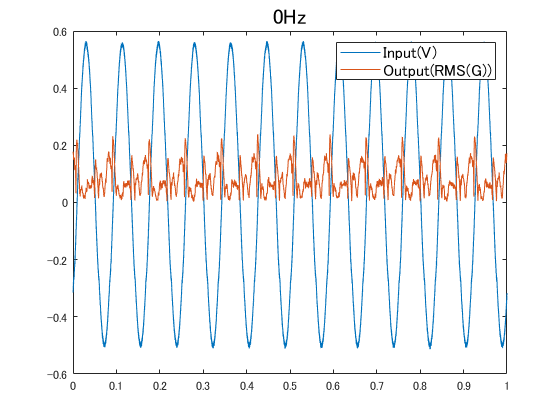

%表示する周波数を選択
hz = 2;
Frequency = num2str(round(Mx{hz,4}-0.5)); %周波数を文字列表示
GraphTitle = strcat(Frequency,'Hz');
% plot(M(:,1), M(:,2))
% hold on
% plot(M(:,1), M(:,3))
% hole off
plot(Mx{hz,2}(:,1), Mx{hz,2}(:,3))
hold on
plot(Mx{hz,2}(:,1), Mx{hz,2}(:,2))
title(GraphTitle, 'fontsize',16)
legend('Input(V)','Output(RMS(G))','fontsize',12);
% plot(Mx{2,2}(:,1), Mx{2,2}(:,3))
% plot(Mx{2,2}(:,1), Mx{2,2}(:,2))
% plot(Mx{3,2}(:,1), Mx{3,2}(:,2))
% plot(Mx{3,2}(:,1), Mx{3,2}(:,3))
hold off